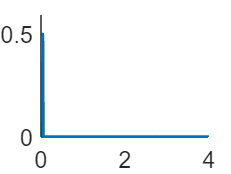

clear all

for l=1:1
    clear biomass1
    clear biomass0
    %filestring=strcat("D1000_biomass_t2500", int2str(l))
    %filestring=strcat(filestring,".m")
    %run(filestring);
    run("D1000_biomass_t30000.m");
        for y=1:400
                heterozygot(y,l)=0.0;
                k=0;
                for x=1:400
                    biomass0(y,x)=biomass_30000_0(y,x);
                    biomass1(y,x)=biomass_30000_1(y,x);
                    if  (biomass0(y,x)+biomass1(y,x))>0.0
                        hetero(y,x)=2*biomass0(y,x)*biomass1(y,x)/((biomass0(y,x)+biomass1(y,x))^2);
                        k=k+1;
                    else
                        hetero(y,x)=0.0;
                    end
                    heterozygot(y,l)=heterozygot(y,l)+hetero(y,x);
                end
                if k==0
                    heterozygot(y,l)=0.0;
                else
                    heterozygot(y,l)=heterozygot(y,l)/k;
                end
            end
    
%     plot((1:400)*0.01,heterozygot(1:400))
%     xlabel("Distance from starting edge (cm)")
%     ylabel("Heterozygosity")
%     ylim([0 0.5])
%     xlim([0 2.5])
%     set(gca, 'FontSize', 14)
%     
%     hold on
end

for y=1:400
    avrgHeterozygot(y)=mean(heterozygot(y,:));
    stdHeterozygot(y)=std(heterozygot(y,:));
    sterrHeterozygot(y)=stdHeterozygot(y)/sqrt(5);
end
hold on
plot((1:400)*0.01,avrgHeterozygot(1:400),'LineWidth',2)
%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))
%xlabel("Distance from starting edge (cm)")
%ylabel("Heterozygosity")
%ylim([0 0.5])
%xlim([0 2.5])
set(gca, 'FontSize', 14)

hold on

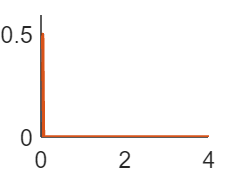




for l=1:1
    clear biomass1
    clear biomass0
    %filestring=strcat("biomass_D10000_t200h_", int2str(l))
    %filestring=strcat(filestring,".m")
    %run(filestring);
    run("D10000_biomass_t20000.m")
        for y=1:400
                heterozygot(y,l)=0.0;
                k=0;
                for x=1:400
                    biomass0(y,x)=biomass_20000_0(y,x);
                    biomass1(y,x)=biomass_20000_1(y,x);
                    if  (biomass0(y,x)+biomass1(y,x))>0.0
                        hetero(y,x)=2*biomass0(y,x)*biomass1(y,x)/((biomass0(y,x)+biomass1(y,x))^2);
                        k=k+1;
                    else
                        hetero(y,x)=0.0;
                    end
                    heterozygot(y,l)=heterozygot(y,l)+hetero(y,x);
                end
                if k==0
                    heterozygot(y,l)=0.0;
                else
                    heterozygot(y,l)=heterozygot(y,l)/k;
                end
            end
    
%     plot((1:400)*0.01,heterozygot(1:400))
%     xlabel("Distance from starting edge (cm)")
%     ylabel("Heterozygosity")
%     ylim([0 0.5])
%     xlim([0 2.5])
%     set(gca, 'FontSize', 14)
%     
%     hold on
end

for y=1:400
    avrgHeterozygot(y)=mean(heterozygot(y,:));
    stdHeterozygot(y)=std(heterozygot(y,:));
    sterrHeterozygot(y)=stdHeterozygot(y)/sqrt(5);
end

hold on
plot((1:400)*0.01,avrgHeterozygot(1:400),'LineWidth',2)

%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))


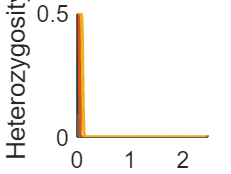


clear heterozygot
for l=1:1
    clear biomass1
    clear biomass0
    %filestring=strcat("biomass_D1000_t475h_", int2str(l+1))
    %filestring=strcat(filestring,".m")
    %run(filestring);
    run("D100000_biomass_t10000.m");
            for y=1:400
                heterozygot(y,l)=0.0;
                k=0;
                for x=1:400
                    biomass0(y,x)=biomass_10000_0(y,x);
                    biomass1(y,x)=biomass_10000_1(y,x);
                    if  (biomass0(y,x)+biomass1(y,x))>0.0
                        hetero(y,x)=2*biomass0(y,x)*biomass1(y,x)/((biomass0(y,x)+biomass1(y,x))^2);
                        k=k+1;
                    else
                        hetero(y,x)=0.0;
                    end
                    heterozygot(y,l)=heterozygot(y,l)+hetero(y,x);
                end
                heterozygot(y,l)=heterozygot(y,l)/k;
            end
    
%     plot((1:400)*0.01,heterozygot(1:400))
%     xlabel("Distance from starting edge (cm)")
%     ylabel("Heterozygosity")
%     ylim([0 0.5])
%     xlim([0 2.5])
%     set(gca, 'FontSize', 14)
%     
%     hold on
end

for y=1:400
    avrgHeterozygot(y)=mean(heterozygot(y,:));
    stdHeterozygot(y)=std(heterozygot(y,:));
    sterrHeterozygot(y)=stdHeterozygot(y)/sqrt(1);
end
hold on
plot((1:400)*0.01,avrgHeterozygot(1:400),'LineWidth',2)
%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))

%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))
%xlabel("Distance from starting edge (cm)")
ylabel("Heterozygosity",'FontSize',30)
ylim([0 0.5])
xlim([0 2.5])
set(gca, 'FontSize', 14)

hold on

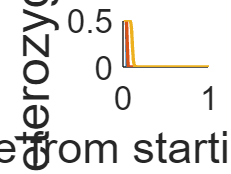

ylim([0 0.5])
xlim([0 1.0])
%h=legend('D_b=600','D_b=60','D_b=6','D_b=0.6 x10^{-3}','Location','east')
rect = [0.60, 0.50, .25, .25];
%set(h, 'Position', rect)
%tex = text(1.05,.18,'(cm^2/sec·g)','FontSize',20)
%legend('boxoff')
set(gca, 'FontSize', 20)
%legend('FontSize', 18)
ylabel("Heterozygosity",'FontSize',30)
xlabel("Distance from starting edge [cm]",'FontSize',27)

% rect = [0.60, 0.55, .25, .25];
% set(h, 'Position', rect)
% legend('boxoff')
% set(gca, 'FontSize', 20)
% legend('FontSize', 12)
%set(gca,'xtick',[])
hold off

%clear all


%semilogy((1:400)*0.01,avrgHeterozygot(1:400))